## MIE301 Lab 1 Case 2

close all; % closes all figures
clear all; % clears all variables from memory
clc;       % clears all calculations from the Matlab workspace

% Plot Parameters: these will be used to set the axis limits on the figure
% using axis()
xmin= -15;  % leftmost window edge
xmax= 15;   % rightmost window edge
ymin= -15; % bottom window edge
ymax= 15;  % top window edge

## Define the link and motion Parameters

stepsize = 30 *pi/180;                          % number of configuration steps to calculate along mechanism rotation
max_rotation_theta2 = 320 *pi/180;              % rotation limit of theta2, radians
theta2 = 0 : stepsize : max_rotation_theta2;    % link 2 rotation into 'increments' number of angles
length2 = 4;                                    % link #2 length
length3 = 8;                                    % link #3 length
phi = 73*pi/180;                                % Constant angle value

AC = sqrt(length2^2+length3^2-2*length2*length3*cos(2*pi-phi))  % Define the length AC

AC = 7.8287

alpha = asin(length3*(sin(2*pi-phi)/AC))

alpha = -1.3570

Theta_c = theta2 - alpha

Theta_c =     1.3570    1.8806    2.4042    2.9278    3.4514    3.9750    4.4986    5.0222    5.5458    6.0694    6.5930


## set up figure

figure(1);                         %create new figure
set(1,'WindowStyle','Docked')      %dock the figure

## calculate mechanism motion and plot it

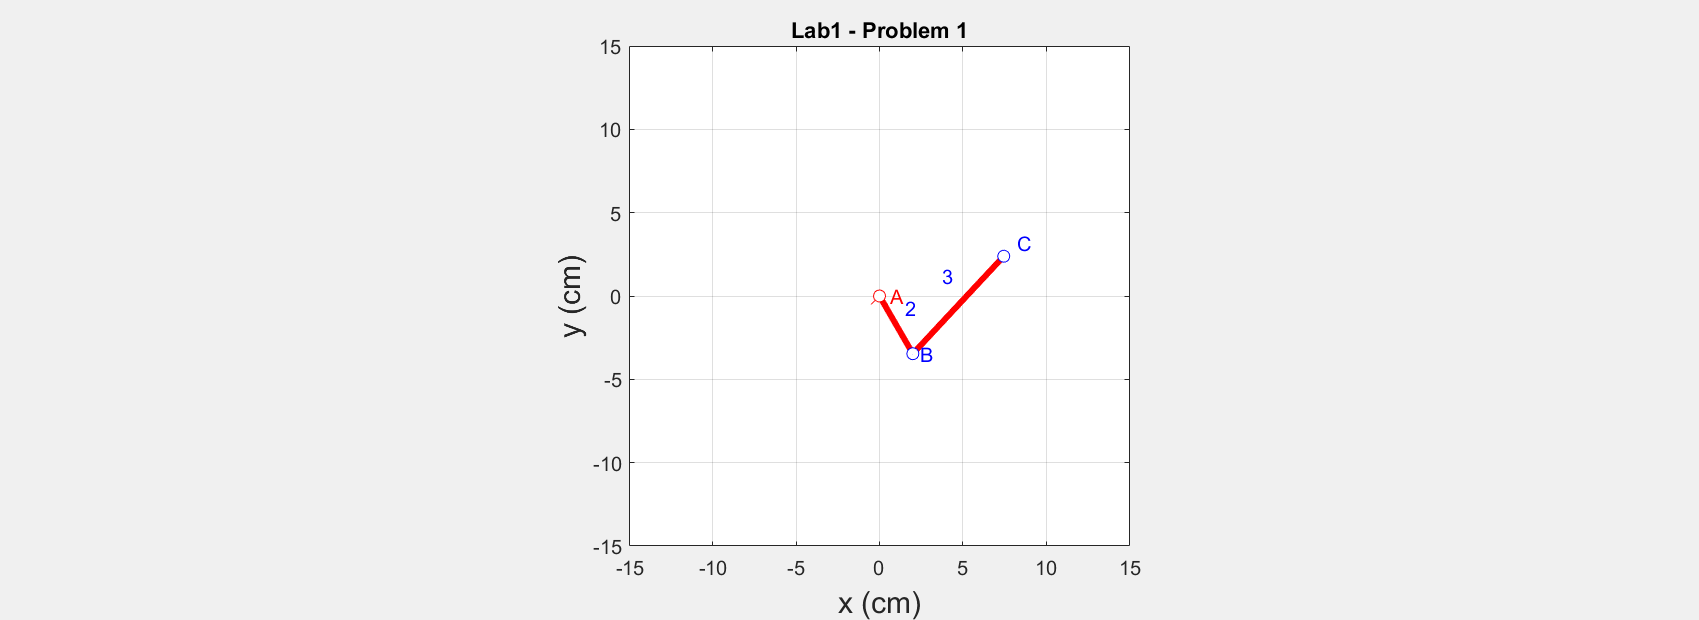

for i=1:length(theta2)                            % step through motion of the mechanism
    hold off;                                     % erase the previously plotted data each cycle
    Ax(i) = 0;                                    % pivot point of link 2 position
    Ay(i) = 0;                                    % pivot point of link 2 position
    Bx(i) = length2*cos( theta2(i) );             % point B position
    By(i) = length2*sin( theta2(i) ); 
    Cx(i) = AC*cos(Theta_c(i));                   % point C position
    Cy(i) = AC*sin(Theta_c(i));

    %hold on;

   
    % point B position
    plot( [Ax(i) Bx(i)], [Ay(i), By(i)],'Color','r','LineWidth',3 ); %draw the link from A to B for the current configuration
    hold on;
    plot( [Bx(i) Cx(i)], [By(i), Cy(i)],'Color','r','LineWidth',3 ); %draw the link from B to C for the current configuration

    hold on;
    
    basePivotSize = .5;                                 %size of drawn base pivot
    plot([0,basePivotSize],[0,-basePivotSize],'r');     %draw base pivot
    plot([0,-basePivotSize],[0,-basePivotSize],'r');    %draw base pivot
    plot(0,0,'ro','MarkerFaceColor','w');               %draw a small circle at the base pivot point
    plot(Bx(i), By(i), 'bo','MarkerFaceColor','w');     %draw a small circle at B
    text(Ax(i)+0.6, Ay(i), 'A','color','r');            %label point A
    text(Bx(i)+0.4, By(i), 'B','color','b');            %label point B
    text(Cx(i)+0.8, Cy(i)+0.8, 'C','color','b');        %label point C
    text(Bx(i)/2+0.5, By(i)/2+1, '2', 'Color','b');           %label link 2
    text(Cx(i)/2, Cy(i)/2, '3', 'Color','b');           %label link 3


    plot(Cx(i), Cy(i), 'bo','MarkerFaceColor','w');     %draw a small circle at B
    plot(Cx(i), Cy(i), 'bo','MarkerFaceColor','w');     %draw a small circle at C


    
    hold on;                            % draw on top of the current figure
    xlabel('x (cm)', 'fontsize', 15);   % axis label
    ylabel('y (cm)', 'fontsize', 15);   % axil label 
    grid on;                            % add a grid to the figure
    axis equal;                         % make sure the figure is not stretched
    title('Lab1 - Problem 1');          % add a title to the figure
    axis( [xmin xmax ymin ymax] );      % set figure axis limits
    
    % TODO:add new code for compute point C position and displaying link3 or segment BC
    % You can either add code below or insert above

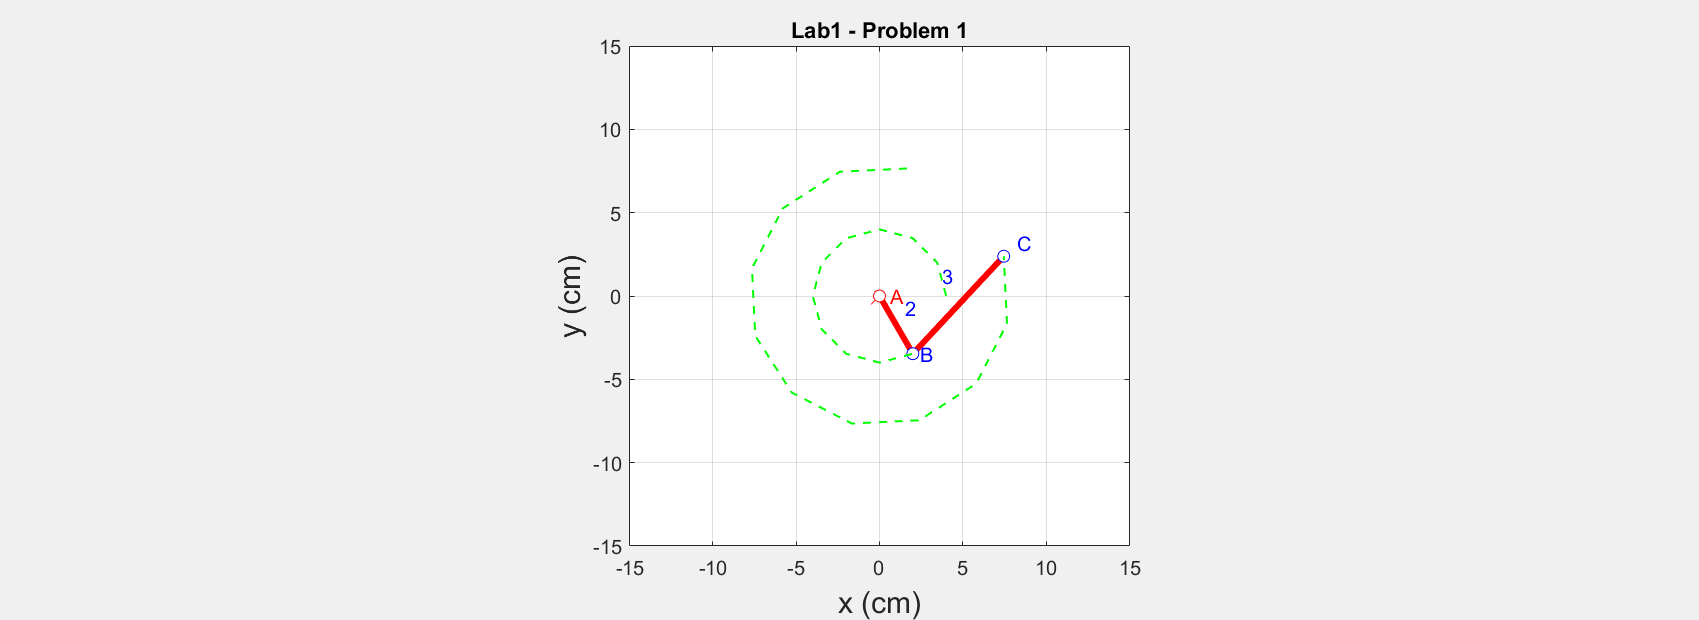

    pause(0.1);                       % wait to proceed to next configuration, in seconds
    
end
plot(Bx(:),By(:),'--g','linewidth',1);  % draw a trace of the path of point B
plot(Cx(:),Cy(:),'--g','linewidth',1);  % draw a trace of the path of point C